# **OrbitalElements2OrbitStateVector**

## **Purpose**

## **History**

## **Standard Gravitational Parameter**

The standard gravitational parameter $$\mu$$ of a celestial body is the product of the gravitational constant G and the mass M of the body. 

mu = 3.98618e14; % [m3/s2] Earth's geocentric gravitational constant

## **Get the Satellite TLE**

ID = 25544;
[TLE] = getSatelliteTLE(ID);

## **Convert to Orbital Elements**

[OE] = TLE2OrbitalElements(TLE);
fprintf(1,['Kepler Elements for satelliteID %d epoch %s:\n' ...
    '\ta [m] = %f\n\te = %f\n\ti [deg] = %f\n\tomega [deg] = %f\n' ...
    '\tOmega [deg] = %f\n\tM [deg] = %f\n'], floor(OE.satelliteID), ...
    datestr(OE.epoch),OE.a_km, OE.e, OE.i_deg, OE.omega_deg, ...
    OE.Omega_deg, OE.M_deg);

Kepler Elements for satelliteID 25544 epoch 20-Sep-2008 12:25:40:
	a [m] = 6731.059508
	e = 0.000670
	i [deg] = 51.641600
	omega [deg] = 130.536000
	Omega [deg] = 247.462700
	M [deg] = 325.028800


a_m = OE.a_km*1e3;
e = OE.e;
M_deg = OE.M_deg;

## **Orbital Plane Coordinates**

In the plane of the orbit:


$$p= a\left ( \cos E - e \right )$$



$$q=a\sqrt{1-e^{2}}\sin E$$


where

$$p$ - [m] coordinate along axis through center and perigee

$$q$ - [m] coordinate along axis passing through focus and perpendicular to the p-axis

$$E$ - [rad] eccentric anomaly

$$e$ - [unitless] eccentricity

## **Mean Motion**

The mean motion, n, is the angular speed required for a body to complete one orbit = 2*pi/Period

n = sqrt(mu/a_m^3);  % [rad/s] mean motion

## **Derivatives Yeild Velocity Components Along Orbit**


$$\dot M = \dot E - e (\cos E) \dot E \\ = n$$



$$\dot E = \dot M / (1 - e \cos E) \\$$



$$\dot P = -a (\sin E) \dot E \qquad $$



$$\dot Q = a (\cos E) \dot E \sqrt{1 - e^2}$$


## **Use Kepler Equation to Find Location Along Orbit**


$$E-e\sin \left ( E \right )= n\left ( t-t_{p} \right )=M$$


where

$$t_{p}$ - [s] time of periapsis

$$n$ - [rad/s] mean motion (in the TLE it is orbits/day)

$$M$ - [rad] mean anomaly

## **Use Newton Method to Solve the Kepler Equation**


$$E_{i+1} = E_i - f(E_i) / f'(E_i) \\$$



$$f'(E) = 1 - e \cos E$$


## **Output Orbit Plane State Vector**

M_rad = deg2rad(M_deg);
E_rad = M_rad; 
dE = 99999;
eps = 1e-6; % [rad] control precision of Newton's method solution
while (abs(dE) > eps)
    dE = (E_rad - e * sin(E_rad) - M_rad)/(1 - e * cos(E_rad));
    E_rad = E_rad -  dE;
end
p_m = a_m*(cos(E_rad) - e);
q_m = a_m*sqrt(1 - e^2)*sin(E_rad);

dMdt_rad_per_s = n;
dEdt_rad_per_s = dMdt_rad_per_s/(1 - e*cos(E_rad));
dpdt_m_per_s = -a_m*sin(E_rad)*dEdt_rad_per_s;
dqdt_m_per_s = a_m*cos(E_rad)*dEdt_rad_per_s*sqrt(1 - e^2);

## **Plot the Plane of the Orbit**

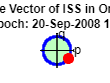

ra_m = a_m*(1 + e);  % [m] apogee 
rp_m = a_m*(1 - e);  % [m] perigee
rEarth_m = 6378e3; % [m] Earth radius at equator
Evals = 0:0.01:360.0; % [deg] values of the eccentric anomaly around orbit 
pvals = a_m*(cosd(Evals)-e); % [m] orbit positions
qvals = a_m*sqrt(1 - e^2)*sind(Evals); % [m] orbit positions

figure('color','white');
fill(rEarth_m.*cosd(Evals),rEarth_m.*sind(Evals),[0.75 1.00 0.75]);
hold on;
plot(pvals,qvals,'.b');
plot(p_m,q_m,'.r','MarkerSize',25);
p1_m = p_m+dpdt_m_per_s*300;
q1_m = q_m+dqdt_m_per_s*300;
plot([p_m p1_m],[q_m q1_m],'r');
theta = -atan2d(dqdt_m_per_s,dpdt_m_per_s);
plot(p1_m+[0 -0.1*rEarth_m*cosd(theta+30)],q1_m+[0  0.1*rEarth_m*sind(theta+30)],'r');
plot(p1_m+[0 -0.1*rEarth_m*cosd(theta-30)],q1_m+[0  0.1*rEarth_m*sind(theta-30)],'r');

% axes
plot([-1.25*rp_m 1.25*rp_m],[0 0],'k');
plot([0 0],[-1.25*ra_m 1.25*ra_m],'k');
text(1.25*rp_m, 0.1*rEarth_m, 'p');
plot(1.25*rp_m+[0 -0.1*rEarth_m*cosd(30)],[0 0.1*rEarth_m*sind(30)],'k');
plot(1.25*rp_m+[0 -0.1*rEarth_m*cosd(30)],[0 -0.1*rEarth_m*sind(30)],'k');
text(0.1*rEarth_m, 1.25*ra_m, 'q');
plot([0 -0.1*rEarth_m*sind(30)],1.25*ra_m+[0 -0.1*rEarth_m*cosd(30)],'k');
plot([0 +0.1*rEarth_m*sind(30)],1.25*ra_m+[0 -0.1*rEarth_m*cosd(30)],'k');

axis equal
axis tight
axis off
box on
title({'Initial State Vector of ISS in Orbital Plane'; ...
    ['TLE Epoch: ' datestr(OE.epoch)]});